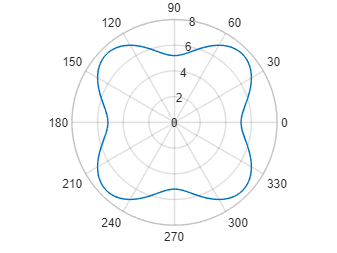

[x, y] = clover(pi/4,1);

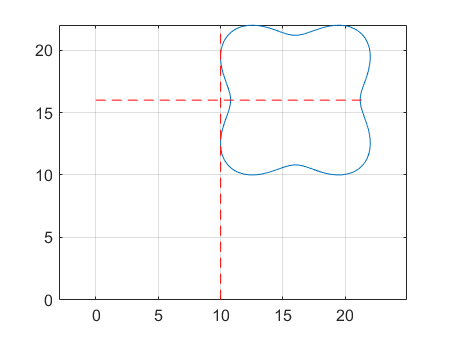


%¿Cuántos cm quiere desplazar el trébol desde su punta inferior?
trasl = 10;
[x, y] = cloverCartesian(x, y, trasl);

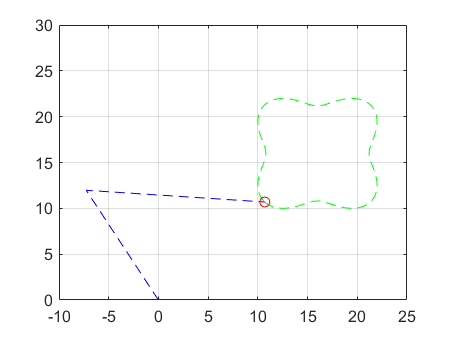


%Distancia total 
longitudTotal = sqrt((max(x)-min(x))^2+((max(y)-min(y))^2))...
                + sqrt(trasl^2*2);
%Información de los brazos
l1 = 14;
l2 = 18;
%Valores semilla
th1 = 80;       
th3 = 20;
%Matriz para almacenar los ángulos
theta = zeros(length(x), 2);
%Loop para calcular los ángulos
for i =1:length(x)
    thGuess = [th1; th3];
    [th1, th3] = position(x(i),y(i),l1,l2,thGuess);
    theta(i,:) = [th1, th3];
end

animation(theta, l1, l2, x, y)

function [x, y] = clover(phi, A)
    B = 5.5;
    theta = linspace(0,2*pi,300);
    theta = theta - 2.356;
    radio = (B + cos(4.*(theta-phi)))*7.5/(B+1)*A;
    polarplot(theta, radio);
    hold off

    x = radio.*cos(theta);
    y = radio.*sin(theta);
end

function [x, y] = cloverCartesian(x, y, trasl)
    maxX = max(x);
    maxY = max(y);

    x = x+maxX+trasl;
    y = y+maxY+trasl;

    horX = [0:0.5:maxX*2+trasl];
    horY = (maxY+trasl)*ones(length(horX));

    vertY = [0:0.5:maxY*2+trasl];
    vertX = trasl*ones(length(vertY));

    f1 = figure(1);
    plot(x, y);
    hold on;
    plot(horX, horY, "--r");
    plot(vertX,vertY, "--r");
    axis equal;
    grid on;
    hold off;

end

function [th1, th3] = position(x,y,l1,l2, thGuess)

    error = 1e-5;
    NF = 1e-5*1000;
    
    while error < abs(NF)
        th1 = thGuess(1);
        th3 = thGuess(2);

        h = sqrt(x^2+y^2);
        phi = atand(y/x);
    
        F = [l1*cosd(th1) + l2*cosd(th3) - h*cosd(phi);
            l1*sind(th1) + l2*sind(th3) - h*sind(phi)];

        J = [-l1*sind(th1), -l2*sind(th3);
            l1*cosd(th1), l2*cosd(th3)];
        Dth = J\(-F);
        
        NF = norm(F);
        thGuess = Dth +thGuess;
    end

end


function animation(theta, l1, l2, x, y)
    %animacion = VideoWriter('animacion'); %open video file
    %animacion.FrameRate = 10;  %can adjust this, 5 - 10 works well for me
    %open(animacion)
    for i = 1:length(theta)
        %Posición de cada una de las juntas
        A = [0,0];
        B = [A(1) + l1*cosd(theta(i,1)), A(2) +...
            l1*sind(theta(i,1))];
        C = [B(1) + l2*cosd(theta(i,2)), B(2) +...
            l2*sind(theta(i,2))];
        
        xJunta = [A(1), B(1), C(1)];
        yJunta = [A(2), B(2), C(2)];
        
        f2 = figure(2);
        plot(x(1:i), y(1:i), "--g")
        hold on

        pl = line(xJunta, yJunta);
        pl.Color = 'blue';
        pl.LineStyle = '--';
        xlim([-10 25])
        ylim([0 30])
        grid on
        plot(x(i), y(i), "or")
        pause(0.05);

        %frame = getframe(gcf); %get frame
        %writeVideo(animacion, frame);
        clf

        if i == length(x)
            plot(x(1:i), y(1:i), "--g")
            hold on
    
            pl = line(xJunta, yJunta);
            pl.Color = 'blue';
            pl.LineStyle = '--';
            xlim([-10 25])
            ylim([0 30])
            grid on
            plot(x(i), y(i), "or")
            pause(0.05);
        end
    end
    %close(animacion)

end
